## **Chameleon Data vs Matlab API Data **

#### A) Testing the Data from Chamelon. This was taken during quiet sitting on the Biodex chair. 

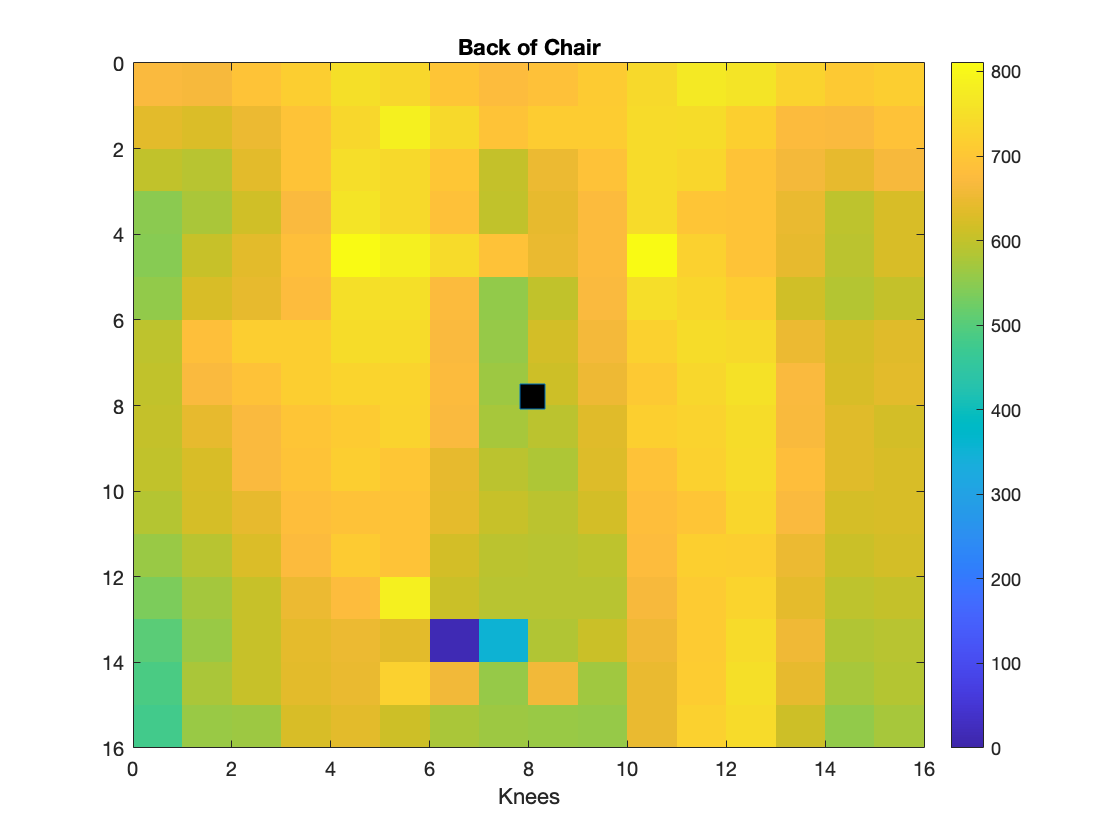

% Loading data
load('ChameleonQuietSittingJass.mat')

ppsdata=quietsittingjassPSI(2:end,:);


% Find the absolute minimum for all the frames

Min_ppsdata= min(min(ppsdata));

%Adding the minimum to all the pressure values so positive
ppsdata = ppsdata+abs(Min_ppsdata);


%Finding maximum for all frames 

Max_ppsdata = max(max(ppsdata));

% Creating and reshaping to resemble pressure mat
TotalPressure1 = sum(ppsdata(:,1:256),2); 


Pressuremat1 = ppsdata(:,1:256);
nframes=size(Pressuremat1 ,1);
        
    for i=1:nframes
        % flipped to align with PPS mat layout
        Pressuremat1_frame(:,:,i) =flipud(reshape(Pressuremat1(i,:),[16,16])');

    end
    
%Calculating COP - elements 1" apart
        
rm=repmat((0:15)'+0.5,1,16); rm=rm'; rm=rm(:);
CoP1=[sum(ppsdata(:,1:256).*repmat((0:15)+0.5,nframes,16),2)./TotalPressure1 sum(ppsdata(:,1:256).*repmat(rm',nframes,1),2)./TotalPressure1]; % mat 1
CoP1(:,2) = 16-CoP1(:,2);

%Creating Figure at first frame

% imagesc(Pressuremat1_frame(:,:,i)+abs(min_Pressuremat1),[50 100])
i=1;
imagesc(.5,.5,Pressuremat1_frame(:,:,i),[0 Max_ppsdata])
hold on
plot(CoP1(i,1),CoP1(i,2),'s','MarkerFaceColor','k','MarkerSize',16)
colorbar
xlabel('Knees')
title('Back of Chair')


% Creating Video
%         
% v = VideoWriter('pps.avi');
% open(v);
%         
%    for i=1:nframes
%    
%        clf
%        % imagesc(Pressuremat1_frame(:,:,i)+abs(min_Pressuremat1),[50 100])
%        imagesc(.5,.5,Pressuremat1_frame(:,:,i),[-20 100])
%        hold on
%        plot(CoP1(i,1),CoP1(i,2),'s','MarkerFaceColor','k','MarkerSize',16)
%        colorbar
%              
%        frame = getframe(gcf);
%        writeVideo(v,frame);
%        pause(.1)
%             
%    end
%         close(v);
%        

#### B) Testing the Data from MATLAB API. This was taken during quiet sitting on the Biodex chair. 

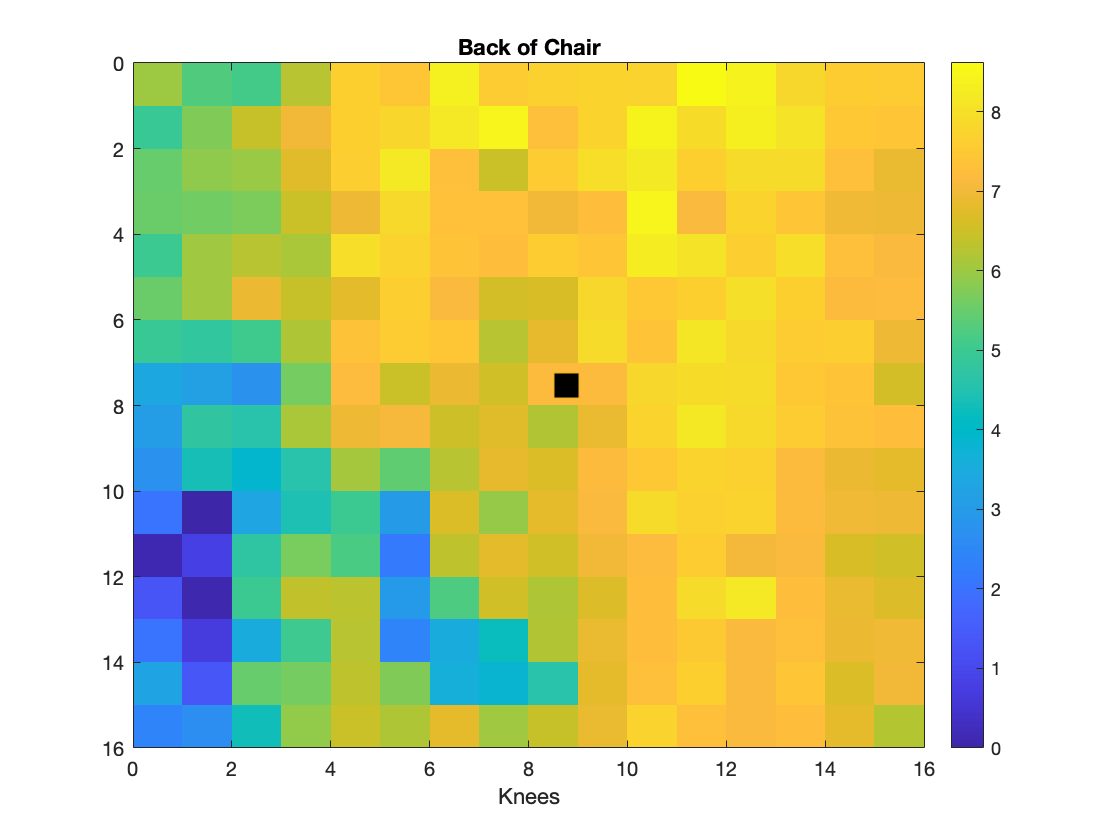

        
% Loading in data
load('JassQuietSittingAPI.mat')

ppsdata=data.pps{1,2};

% Find the absolute minimum for all the frames

Min_ppsdata= min(min(ppsdata));

%Adding the minimum to all the pressure values so positive
ppsdata = ppsdata+abs(Min_ppsdata);


%Finding maximum for all frames 

Max_ppsdata = max(max(ppsdata));

% Creating and reshaping to resemble pressure mat
TotalPressure1 = sum(ppsdata(:,1:256),2); 


Pressuremat1 = ppsdata(:,1:256);
nframes=size(Pressuremat1 ,1);
        
    for i=1:nframes
        % flipped to align with PPS mat layout
        Pressuremat1_frame(:,:,i) =flipud(reshape(Pressuremat1(i,:),[16,16])');

    end

    
     
%Calculating COP - elements 1" apart
        
rm=repmat((0:15)'+0.5,1,16); rm=rm'; rm=rm(:);
CoP1=[sum(ppsdata(:,1:256).*repmat((0:15)+0.5,nframes,16),2)./TotalPressure1 sum(ppsdata(:,1:256).*repmat(rm',nframes,1),2)./TotalPressure1]; % mat 1
CoP1(:,2) = 16- CoP1(:,2);


% imagesc(Pressuremat1_frame(:,:,i)+abs(min_Pressuremat1),[50 100])
i=1;
imagesc(.5,.5,Pressuremat1_frame(:,:,i),[0 Max_ppsdata])
hold on
plot(CoP1(i,1),CoP1(i,2),'s','MarkerFaceColor','k','MarkerSize',16)
colorbar
xlabel('Knees')
title('Back of Chair')


% Creating Video
%         
% v = VideoWriter('pps.avi');
% open(v);
%         
%    for i=1:nframes
%    
%        clf
%        % imagesc(Pressuremat1_frame(:,:,i)+abs(min_Pressuremat1),[50 100])
%        imagesc(.5,.5,Pressuremat1_frame(:,:,i),[-20 100])
%        hold on
%        plot(CoP1(i,1),CoP1(i,2),'s','MarkerFaceColor','k','MarkerSize',16)
%        colorbar
%              
%        frame = getframe(gcf);
%        writeVideo(v,frame);
%        pause(.1)
%             
%    end
%         close(v);


